x_max = 55;
N_max_gr = 8;
gamma0 = 0;
gamma1 = 1;
gamma2 = 3;

x_eff = 11.8;
x_eff_real = 16;
psi = 0.96;
psi_real = 1.008;
A = [1.0075 1.0095 1.01]';
A_real = [1.0018 1.016 1.009]';
% I'm not going to bother writing out the group number bit since it will
% cancel with the 10
B = [1.65 2.07 2.47]';
B_real = [1.6969 2.2175 2.6709]';
lambda = 700;

x_con_init = [20 22 25 27 17]; 
x_aux_init = [6 6 7 7 8];

parameters_real = struct( ...
    'x_max', x_max, ...
    'N_max_gr', N_max_gr, ...
    'gamma0', gamma0, ...
    'gamma1', gamma1, ...
    'gamma2', gamma2, ...
    'x_eff', x_eff_real, ...
    'psi', psi_real, ...
    'A', A_real, ...
    'B', B_real, ...
    'lambda', lambda);

parameters_pred = struct( ...
    'x_max', x_max, ...
    'N_max_gr', N_max_gr, ...
    'gamma0', gamma0, ...
    'gamma1', gamma1, ...
    'gamma2', gamma2, ...
    'x_eff', x_eff, ...
    'psi', psi, ...
    'A', A, ...
    'B', B, ...
    'lambda', lambda);


Np = 6;
parameters = parameters_real;

xk = [55;8];
[a,b,c] = functionForAll2(Np, xk, parameters, 0)

a =      0
     0


b = 0

c = 1000000

## 2.5) MPC

run = false;
if run
    % RUN 1 - Np = 6
    finduOpt = @(xk) functionForAll2(Np, xk, parameters_pred, -1);
    realUpdate = @(xk, uk) functionForAll2(Np, xk, parameters_real, uk);
    
    
    %[x_next, u_opt, J_opt] = realUpdate(xk, 0)
    
    T_end = 60; 
    
    xk_6 = zeros(2,5, T_end + 1); % xcon/xaux, section, time
    u_k_6 = zeros(5,T_end+1)
    xk_6(:, :, 1) = [x_con_init ; x_aux_init]; % Set initial conditions
    total_cost = 0;
    tic
    for i = 2:T_end+1
        disp("x_k = " + num2str(xk_6(:,:,i-1)))
        disp("time_elapsed = " + num2str(toc) + "seconds")
        disp("time step " + num2str(i-1) + " of " + num2str(T_end))
        for j = 1:5
            [~,u_k_6(j,i), ~] = finduOpt(xk_6(:,j,i-1)); 
            [xk_6(:,j,i), ~, J] = realUpdate(xk_6(:,j,i-1), u_k_6(j,i));
            total_cost = total_cost + J;
        end
    end

    % RUN 2 - Np = 15
    Np = 15;
    finduOpt = @(xk) functionForAll2(Np, xk, parameters_pred, -1);
    realUpdate = @(xk, uk) functionForAll2(Np, xk, parameters_real, uk);
    
    
    %[x_next, u_opt, J_opt] = realUpdate(xk, 0)
    
    T_end = 60; 
    
    xk_15 = zeros(2,5, T_end + 1); % xcon/xaux, section, time
    u_k_15 = zeros(5,T_end+1);
    xk_15(:, :, 1) = [x_con_init ; x_aux_init]; % Set initial conditions
    total_cost = 0;
    tic
    for i = 2:T_end+1
        disp("x_k = " + num2str(xk_15(:,:,i-1)))
        disp("time_elapsed = " + num2str(toc) + "seconds")
        disp("time step " + num2str(i-1) + " of " + num2str(T_end))
        for j = 1:5
            [~,u_k_15(j,i), ~] = finduOpt(xk_15(:,j,i-1)); 
            [xk_15(:,j,i), ~, J] = realUpdate(xk_15(:,j,i-1), u_k_15(j,i));
            total_cost = total_cost + J;
        end
    end


end

u_k_6 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

    "x_k = 20  22  25  27  17"
    "x_k =  6   6   7   7   8"



time_elapsed = 0.0047576seconds


time step 1 of 60


    "x_k = 21.7329      23.7365      26.7419      28.7455      18.7275"
    "x_k =       6            6            7            7            8"



time_elapsed = 0.21415seconds


time step 2 of 60


    "x_k = 23.4689      25.4761      28.4869      30.4941      20.4581"
    "x_k =       6            6            7            7            8"



time_elapsed = 0.48275seconds


time step 3 of 60


    "x_k = 25.2081      27.2189      30.2351      33.1995      22.1918"
    "x_k =       6            6            7            7            8"



time_elapsed = 0.72461seconds


time step 4 of 60


    "x_k = 26.9503      28.9648      32.9364      35.9482      23.9287"
    "x_k =       6            6            7            7            8"



time_elapsed = 1.0051seconds


time step 5 of 60


    "x_k = 28.6957      30.7138      35.6809      38.7409      25.6687"
    "x_k =       6            6            7            7            8"



time_elapsed = 1.2191seconds


time step 6 of 60


    "x_k = 30.4443      33.4227      38.4692      41.5783      27.4118"
    "x_k =       6            6            7            7            8"



time_elapsed = 1.4876seconds


time step 7 of 60


    "x_k = 33.1489       36.175      41.3023       44.461       29.158"
    "x_k =       6            6            7            7            8"



time_elapsed = 1.7497seconds


time step 8 of 60


    "x_k = 35.8968      38.9713      44.1806      47.3899      30.9074"
    "x_k =       6            6            7            7            8"



time_elapsed = 2.048seconds


time step 9 of 60


    "x_k = 38.6886      41.8123       47.105       31.641      33.6194"
    "x_k =       6            6            7            8            8"



time_elapsed = 2.3795seconds


time step 10 of 60


    "x_k = 41.5252      44.6988      31.3538      34.3648      36.3748"
    "x_k =       6            6            8            8            8"



time_elapsed = 2.6211seconds


time step 11 of 60


    "x_k = 44.4071      28.9284       34.073      37.1321      39.1743"
    "x_k =       6            7            8            8            8"



time_elapsed = 2.8677seconds


time step 12 of 60


    "x_k = 28.6343      30.6774      36.8357      39.9437      42.0186"
    "x_k =       7            7            8            8            8"



time_elapsed = 3.1837seconds


time step 13 of 60


    "x_k = 30.3828      33.3857      39.6425      42.8003      44.9084"
    "x_k =       7            7            8            8            8"



time_elapsed = 3.4028seconds


time step 14 of 60


    "x_k = 33.0864      36.1374      42.4943      45.7026      47.8444"
    "x_k =       7            7            8            8            8"



time_elapsed = 3.6781seconds


time step 15 of 60


    "x_k = 35.8333      38.9331      45.3917      48.6514      50.8274"
    "x_k =       7            7            8            8            8"



time_elapsed = 3.8956seconds


time step 16 of 60


    "x_k = 38.6241      41.7735      48.3355      51.6473            0"
    "x_k =       7            7            8            8            0"



time_elapsed = 4.0929seconds


time step 17 of 60


    "x_k = 41.4596      44.6594      51.3263            0       1.6969"
    "x_k =       7            7            8            0            0"



time_elapsed = 4.244seconds


time step 18 of 60


    "x_k = 44.3404      47.5915            0       1.6969      3.39685"
    "x_k =       7            7            0            0            0"



time_elapsed = 4.3892seconds


time step 19 of 60


    "x_k = 47.2674      50.5704       1.6969      3.39685      5.09987"
    "x_k =       7            7            0            0            0"



time_elapsed = 4.5629seconds


time step 20 of 60


    "x_k = 31.5175       34.847      3.39685      5.09987      6.80595"
    "x_k =       8            8            0            0            0"



time_elapsed = 4.7183seconds


time step 21 of 60


    "x_k = 34.2393       37.622      5.09987      6.80595       8.5151"
    "x_k =       8            8            0            0            0"



time_elapsed = 4.8318seconds


time step 22 of 60


    "x_k = 37.0046      40.4415      6.80595       8.5151      10.2273"
    "x_k =       8            8            0            0            0"



time_elapsed = 4.9501seconds


time step 23 of 60


    "x_k = 39.8142      43.3061       8.5151      10.2273      11.9426"
    "x_k =       8            8            0            0            0"



time_elapsed = 5.0671seconds


time step 24 of 60


    "x_k = 42.6687      46.2165      10.2273      11.9426       13.661"
    "x_k =       8            8            0            0            0"



time_elapsed = 5.1653seconds


time step 25 of 60


    "x_k = 45.5689      49.1734      11.9426       13.661      15.3825"
    "x_k =       8            8            0            0            0"



time_elapsed = 5.2978seconds


time step 26 of 60


    "x_k = 48.5155            0       13.661      15.3825      17.1071"
    "x_k =       8            0            0            0            0"



time_elapsed = 5.38seconds


time step 27 of 60


    "x_k = 51.5093       1.6969      15.3825      17.1071      18.8348"
    "x_k =       8            0            0            0            0"



time_elapsed = 5.4579seconds


time step 28 of 60


    "x_k = 0      3.39685      17.1071      18.8348      20.5656"
    "x_k = 0            0            0            0            0"



time_elapsed = 5.5643seconds


time step 29 of 60


    "x_k = 1.6969      5.09987      18.8348      20.5656      22.2995"
    "x_k =      0            0            0            0            0"



time_elapsed = 5.6439seconds


time step 30 of 60


    "x_k = 3.39685      6.80595      20.5656      22.2995      24.0366"
    "x_k =       0            0            0            0            0"



time_elapsed = 5.7436seconds


time step 31 of 60


    "x_k = 5.09987       8.5151      22.2995      24.0366      25.7767"
    "x_k =       0            0            0            0            0"



time_elapsed = 5.8359seconds


time step 32 of 60


    "x_k = 6.80595      10.2273      24.0366      25.7767        27.52"
    "x_k =       0            0            0            0            0"



time_elapsed = 5.9639seconds


time step 33 of 60


    "x_k = 8.5151      11.9426      25.7767        27.52      29.2665"
    "x_k =      0            0            0            0            0"



time_elapsed = 6.0801seconds


time step 34 of 60


    "x_k = 10.2273       13.661        27.52      29.2665       31.016"
    "x_k =       0            0            0            0            0"



time_elapsed = 6.2182seconds


time step 35 of 60


    "x_k = 11.9426      15.3825      29.2665       31.016      33.7298"
    "x_k =       0            0            0            0            0"



time_elapsed = 6.3588seconds


time step 36 of 60


    "x_k = 13.661      17.1071       31.016      33.7298       36.487"
    "x_k =      0            0            0            0            0"



time_elapsed = 6.5004seconds


time step 37 of 60


    "x_k = 15.3825      18.8348      33.7298       36.487      39.2883"
    "x_k =       0            0            0            0            0"



time_elapsed = 6.646seconds


time step 38 of 60


    "x_k = 17.1071      20.5656       36.487      39.2883      42.1344"
    "x_k =       0            0            0            0            0"



time_elapsed = 6.7985seconds


time step 39 of 60


    "x_k = 18.8348      22.2995      39.2883      42.1344       45.026"
    "x_k =       0            0            0            0            0"



time_elapsed = 6.9363seconds


time step 40 of 60


    "x_k = 20.5656      24.0366      42.1344       45.026      29.2582"
    "x_k =       0            0            0            0            1"



time_elapsed = 7.0821seconds


time step 41 of 60


    "x_k = 22.2995      25.7767       45.026      29.2582      31.0078"
    "x_k =       0            0            0            1            1"



time_elapsed = 7.2523seconds


time step 42 of 60


    "x_k = 24.0366        27.52      29.2582      31.0078      33.7214"
    "x_k =       0            0            1            1            1"



time_elapsed = 7.4498seconds


time step 43 of 60


    "x_k = 25.7767      29.2665      31.0078      33.7214      36.4785"
    "x_k =       0            0            1            1            1"



time_elapsed = 7.6334seconds


time step 44 of 60


    "x_k = 27.52       31.016      33.7214      36.4785      39.2796"
    "x_k =     0            0            1            1            1"



time_elapsed = 7.843seconds


time step 45 of 60


    "x_k = 29.2665      33.7298      36.4785      39.2796      42.1256"
    "x_k =       0            0            1            1            1"



time_elapsed = 8.0278seconds


time step 46 of 60


    "x_k = 31.016       36.487      39.2796      42.1256      45.0171"
    "x_k =      0            0            1            1            1"



time_elapsed = 8.257seconds


time step 47 of 60


    "x_k = 33.7298      39.2883      42.1256      45.0171      29.2492"
    "x_k =       0            0            1            1            2"



time_elapsed = 8.4868seconds


time step 48 of 60


    "x_k = 36.487      42.1344      45.0171      29.2492      30.9988"
    "x_k =      0            0            1            2            2"



time_elapsed = 8.7035seconds


time step 49 of 60


    "x_k = 39.2883       45.026      29.2492      30.9988      33.7123"
    "x_k =       0            0            2            2            2"



time_elapsed = 8.8989seconds


time step 50 of 60


    "x_k = 42.1344      29.2582      30.9988      33.7123      36.4692"
    "x_k =       0            1            2            2            2"



time_elapsed = 9.096seconds


time step 51 of 60


    "x_k = 45.026      31.0078      33.7123      36.4692      39.2702"
    "x_k =      0            1            2            2            2"



time_elapsed = 9.3549seconds


time step 52 of 60


    "x_k = 29.2582      33.7214      36.4692      39.2702       42.116"
    "x_k =       1            1            2            2            2"



time_elapsed = 9.5767seconds


time step 53 of 60


    "x_k = 31.0078      36.4785      39.2702       42.116      45.0074"
    "x_k =       1            1            2            2            2"



time_elapsed = 9.8597seconds


time step 54 of 60


    "x_k = 33.7214      39.2796       42.116      45.0074      29.2394"
    "x_k =       1            1            2            2            3"



time_elapsed = 10.0985seconds


time step 55 of 60


    "x_k = 36.4785      42.1256      45.0074      29.2394      30.9889"
    "x_k =       1            1            2            3            3"



time_elapsed = 10.3535seconds


time step 56 of 60


    "x_k = 39.2796      45.0171      29.2394      30.9889      33.7023"
    "x_k =       1            1            3            3            3"



time_elapsed = 10.6167seconds


time step 57 of 60


    "x_k = 42.1256      29.2492      30.9889      33.7023       36.459"
    "x_k =       1            2            3            3            3"



time_elapsed = 10.8555seconds


time step 58 of 60


    "x_k = 45.0171      30.9988      33.7023       36.459      39.2599"
    "x_k =       1            2            3            3            3"



time_elapsed = 11.1146seconds


time step 59 of 60


    "x_k = 29.2492      33.7123       36.459      39.2599      42.1055"
    "x_k =       2            2            3            3            3"



time_elapsed = 11.3965seconds


time step 60 of 60


Np = 15

u_k_15 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

    "x_k = 20  22  25  27  17"
    "x_k =  6   6   7   7   8"



time_elapsed = 0.0024261seconds


time step 1 of 60


    "x_k = 21.7329      23.7365      26.7419      28.7455      18.7275"
    "x_k =       6            6            7            7            8"



time_elapsed = 38.6666seconds


time step 2 of 60


    "x_k = 23.4689      25.4761      28.4869      30.4941      20.4581"
    "x_k =       6            6            7            7            8"



time_elapsed = 93.2381seconds


time step 3 of 60


    "x_k = 25.2081      27.2189      30.2351      14.6101      22.1918"
    "x_k =       6            6            7            8            8"



time_elapsed = 173.5851seconds


time step 4 of 60


    "x_k = 26.9503      28.9648       14.349      16.3333      23.9287"
    "x_k =       6            6            8            8            8"



time_elapsed = 224.2876seconds


time step 5 of 60


    "x_k = 28.6957      30.7138      16.0717      18.0596      25.6687"
    "x_k =       6            6            8            8            8"



time_elapsed = 282.4858seconds


time step 6 of 60


    "x_k = 30.4443      33.4227      17.7976       19.789      27.4118"
    "x_k =       6            6            8            8            8"



time_elapsed = 355.6566seconds


time step 7 of 60


    "x_k = 33.1489      17.5621      19.5265      21.5215       29.158"
    "x_k =       6            7            8            8            8"



time_elapsed = 408.9142seconds


time step 8 of 60


    "x_k = 35.8968      19.2906      21.2585      23.2572      30.9074"
    "x_k =       6            7            8            8            8"



time_elapsed = 444.477seconds


time step 9 of 60


    "x_k = 20.056      21.0223      22.9937      24.9959      33.6194"
    "x_k =      7            7            8            8            8"



time_elapsed = 511.5912seconds


time step 10 of 60


    "x_k = 21.789       22.757       24.732      26.7378      36.3748"
    "x_k =      7            7            8            8            8"



time_elapsed = 530.3894seconds


time step 11 of 60


    "x_k = 23.5251      6.81105      26.4734      28.4828      39.1743"
    "x_k =       7            8            8            8            8"



time_elapsed = 561.7307seconds


time step 12 of 60


    "x_k = 7.58529      8.52021       28.218       30.231      42.0186"
    "x_k =       8            8            8            8            8"



time_elapsed = 583.1673seconds


time step 13 of 60


    "x_k = 9.29584      10.2324      29.9656      32.9322      44.9084"
    "x_k =       8            8            8            8            8"



time_elapsed = 648.2995seconds


time step 14 of 60


    "x_k = 11.0095      11.9478      31.7165      35.6766      47.8444"
    "x_k =       8            8            8            8            8"



time_elapsed = 701.9926seconds


time step 15 of 60


    "x_k = 12.7262      13.6662      34.4415      38.4649            0"
    "x_k =       8            8            8            8            0"



time_elapsed = 714.4619seconds


time step 16 of 60


    "x_k = 14.446      15.3877        37.21      41.2979       1.6969"
    "x_k =      8            8            8            8            0"



time_elapsed = 735.0345seconds


time step 17 of 60


    "x_k = 16.1689      17.1123      40.0229      44.1762      3.39685"
    "x_k =       8            8            8            8            0"



time_elapsed = 926.1471seconds


time step 18 of 60


    "x_k = 17.8949        18.84      42.8807      47.1005      5.09987"
    "x_k =       8            8            8            8            0"



time_elapsed = 993.6596seconds


time step 19 of 60


    "x_k = 19.624      20.5708      45.7843      50.0716      6.80595"
    "x_k =      8            8            8            8            0"



time_elapsed = 1051.1415seconds


time step 20 of 60


    "x_k = 21.3562      22.3047      48.7344      53.1931       8.5151"
    "x_k =       8            8            8            8            0"



time_elapsed = 1075.1525seconds


time step 21 of 60


    "x_k = 23.0916      24.0418      51.7316            0      10.2273"
    "x_k =       8            8            8            0            0"



time_elapsed = 1086.9714seconds


time step 22 of 60


    "x_k = 24.83      25.7819      54.8681       1.6969      11.9426"
    "x_k =     8            8            8            0            0"



time_elapsed = 1117.8366seconds


time step 23 of 60


    "x_k = 26.5716      27.5252            0      3.39685       13.661"
    "x_k =       8            8            0            0            0"



time_elapsed = 1141.7274seconds


time step 24 of 60


    "x_k = 28.3164      29.2717       1.6969      5.09987      15.3825"
    "x_k =       8            8            0            0            0"



time_elapsed = 1174.5353seconds


time step 25 of 60


    "x_k = 30.0642      31.0213      3.39685      6.80595      17.1071"
    "x_k =       8            8            0            0            0"



time_elapsed = 1203.8302seconds


time step 26 of 60


    "x_k = 32.7628      33.7351      5.09987       8.5151      18.8348"
    "x_k =       8            8            0            0            0"



time_elapsed = 1226.8419seconds


time step 27 of 60


    "x_k = 0      36.4924      6.80595      10.2273      20.5656"
    "x_k = 0            8            0            0            0"



time_elapsed = 1276.3271seconds


time step 28 of 60


    "x_k = 1.6969      39.2938       8.5151      11.9426      22.2995"
    "x_k =      0            8            0            0            0"



time_elapsed = 1315.6417seconds


time step 29 of 60


    "x_k = 3.39685        42.14      10.2273       13.661      24.0366"
    "x_k =       0            8            0            0            0"



time_elapsed = 1421.8661seconds


time step 30 of 60


    "x_k = 5.09987      45.0317      11.9426      15.3825      25.7767"
    "x_k =       0            8            0            0            0"



time_elapsed = 1622.5269seconds


time step 31 of 60


    "x_k = 6.80595      47.9697       13.661      17.1071        27.52"
    "x_k =       0            8            0            0            0"



time_elapsed = 1779.0009seconds


time step 32 of 60


    "x_k = 8.5151            0      15.3825      18.8348      29.2665"
    "x_k =      0            0            0            0            0"



time_elapsed = 1814.1231seconds


time step 33 of 60


    "x_k = 10.2273       1.6969      17.1071      20.5656       31.016"
    "x_k =       0            0            0            0            0"



time_elapsed = 1834.5323seconds


time step 34 of 60


    "x_k = 11.9426      3.39685      18.8348      22.2995      33.7298"
    "x_k =       0            0            0            0            0"



time_elapsed = 1848.5811seconds


time step 35 of 60


    "x_k = 13.661      5.09987      20.5656      24.0366       36.487"
    "x_k =      0            0            0            0            0"



time_elapsed = 1866.306seconds


time step 36 of 60


    "x_k = 15.3825      6.80595      22.2995      25.7767      39.2883"
    "x_k =       0            0            0            0            0"



time_elapsed = 1903.9641seconds


time step 37 of 60


    "x_k = 17.1071       8.5151      24.0366        27.52      42.1344"
    "x_k =       0            0            0            0            0"



time_elapsed = 1947.0106seconds


time step 38 of 60


    "x_k = 18.8348      10.2273      25.7767      29.2665      26.3435"
    "x_k =       0            0            0            0            1"



time_elapsed = 2004.4015seconds


time step 39 of 60


    "x_k = 20.5656      11.9426        27.52       31.016      28.0878"
    "x_k =       0            0            0            0            1"



time_elapsed = 2037.1533seconds


time step 40 of 60


    "x_k = 22.2995       13.661      29.2665      33.7298      29.8352"
    "x_k =       0            0            0            0            1"



time_elapsed = 2088.5013seconds


time step 41 of 60


    "x_k = 24.0366      15.3825       31.016       36.487      31.5858"
    "x_k =       0            0            0            0            1"



time_elapsed = 2131.1084seconds


time step 42 of 60


    "x_k = 25.7767      17.1071      33.7298      39.2883      34.3087"
    "x_k =       0            0            0            0            1"



time_elapsed = 2189.8178seconds


time step 43 of 60


    "x_k = 27.52      18.8348       36.487      42.1344      37.0751"
    "x_k =     0            0            0            0            1"



time_elapsed = 2254.4153seconds


time step 44 of 60


    "x_k = 29.2665      20.5656      39.2883      26.3435      39.8859"
    "x_k =       0            0            0            1            1"



time_elapsed = 2396.2906seconds


time step 45 of 60


    "x_k = 31.016      22.2995      42.1344      28.0878      42.7415"
    "x_k =      0            0            0            1            1"



time_elapsed = 2488.2405seconds


time step 46 of 60


    "x_k = 33.7298      24.0366      26.3435      29.8352      26.9555"
    "x_k =       0            0            1            1            2"



time_elapsed = 2583.4796seconds


time step 47 of 60


    "x_k = 36.487      25.7767      28.0878      31.5858      28.7009"
    "x_k =      0            0            1            1            2"



time_elapsed = 2662.7242seconds


time step 48 of 60


    "x_k = 39.2883        27.52      29.8352      34.3087      30.4494"
    "x_k =       0            0            1            1            2"



time_elapsed = 2721.6895seconds


time step 49 of 60


    "x_k = 42.1344      29.2665      31.5858      37.0751      33.1541"
    "x_k =       0            0            1            1            2"



time_elapsed = 2804.5508seconds


time step 50 of 60


    "x_k = 26.3435       31.016      34.3087      39.8859      35.9021"
    "x_k =       1            0            1            1            2"



time_elapsed = 2901.4486seconds


time step 51 of 60


    "x_k = 28.0878      33.7298      37.0751      42.7415       38.694"
    "x_k =       1            0            1            1            2"



time_elapsed = 3038.7091seconds


time step 52 of 60


    "x_k = 29.8352       36.487      39.8859      26.9555      41.5306"
    "x_k =       1            0            1            2            2"



time_elapsed = 3227.8734seconds


time step 53 of 60


    "x_k = 31.5858      39.2883      42.7415      28.7009      44.4126"
    "x_k =       1            0            1            2            2"



time_elapsed = 3396.9229seconds


time step 54 of 60


    "x_k = 34.3087      42.1344      26.9555      30.4494      28.6399"
    "x_k =       1            0            2            2            3"



time_elapsed = 3552.4201seconds


time step 55 of 60


    "x_k = 37.0751      26.3435      28.7009      33.1541      30.3884"
    "x_k =       1            1            2            2            3"



time_elapsed = 3703.1844seconds


time step 56 of 60


    "x_k = 39.8859      28.0878      30.4494      35.9021      14.5035"
    "x_k =       1            1            2            2            4"



time_elapsed = 3880.0496seconds


time step 57 of 60


    "x_k = 42.7415      29.8352      33.1541       38.694      16.2265"
    "x_k =       1            1            2            2            4"



time_elapsed = 4005.0246seconds


time step 58 of 60


    "x_k = 26.9555      31.5858      35.9021      41.5306      17.9526"
    "x_k =       2            1            2            2            4"



time_elapsed = 4139.2174seconds


time step 59 of 60


    "x_k = 28.7009      34.3087       38.694      44.4126      19.6818"
    "x_k =       2            1            2            2            4"



time_elapsed = 4255.8003seconds


time step 60 of 60


## 2.5a) Plotting data

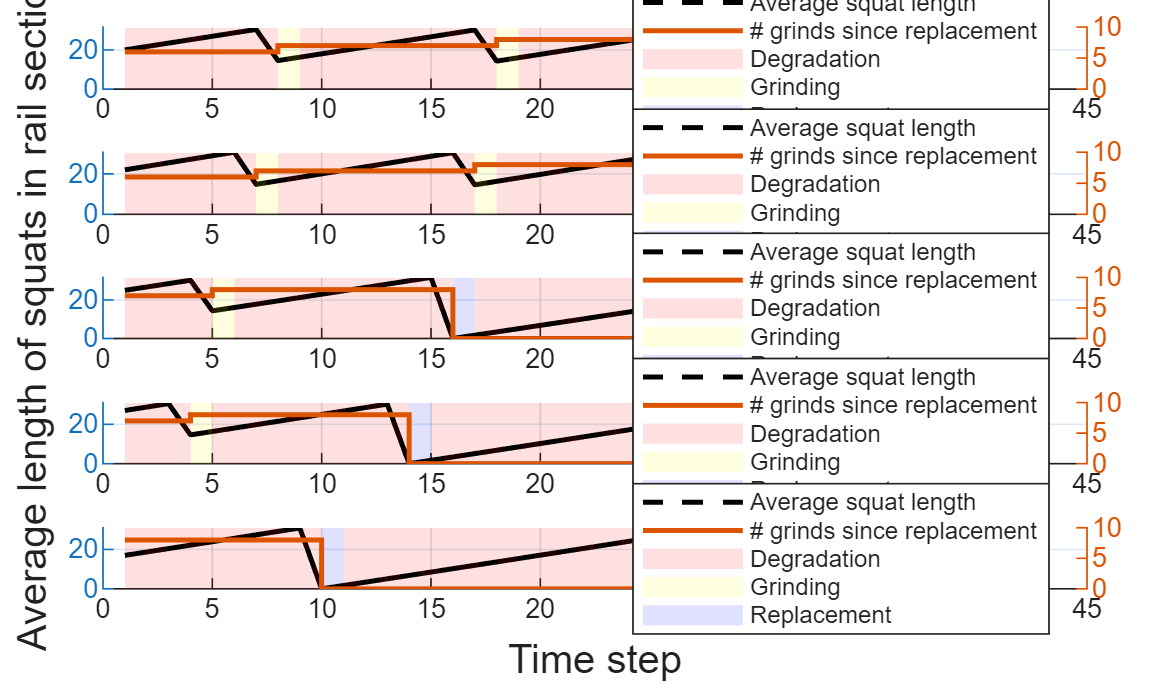

t = 1:T_end+1;

figure;
bigPlot = tiledlayout(5,1,'TileSpacing','compact','Padding','compact');

xlabel(bigPlot,'Time step')
ylabel(bigPlot,'Average length of squats in rail section')

for j = 1:5

    ax = nexttile;
    hold(ax,'on')
    grid(ax,'on')

    y_cont = squeeze(xk(1,j,:));
    y_disc = squeeze(xk(2,j,:));
    colour_state = squeeze(u_k(j,:));

    % ---------------------------
    % Continuous signal
    % ---------------------------
    yyaxis(ax,'left')
    h_cont = plot(ax,t,y_cont,'k','LineWidth',1.5);

    drawnow
    yl = ylim(ax);

    % ---------------------------
    % Background colour regions
    % ---------------------------
    for k = 1:length(t)-1

        switch colour_state(k)

            case 0
                c = [1 0 0]; % red

            case 1
                c = [1 1 0]; % yellow

            case 2
                c = [0 0 1]; % blue

            otherwise
                c = [0.8 0.8 0.8];
        end

        patch(ax,...
            [t(k) t(k+1) t(k+1) t(k)],...
            [yl(1) yl(1) yl(2) yl(2)],...
            c,...
            'FaceAlpha',0.12,...
            'EdgeColor','none',...
            'HandleVisibility','off');   % prevents legend duplication
    end

    % redraw line on top of patches
    yyaxis(ax,'left')
    h_cont = plot(ax,t,y_cont,'k','LineWidth',1.5);

    % ---------------------------
    % Discrete signal
    % ---------------------------
    yyaxis(ax,'right')
    h_disc = stairs(ax,t,y_disc,'LineWidth',1.5);

    % ---------------------------
    % Dummy objects for legend
    % ---------------------------
    h_red    = patch(nan,nan,[1 0 0],'FaceAlpha',0.12,'EdgeColor','none');
    h_yellow = patch(nan,nan,[1 1 0],'FaceAlpha',0.12,'EdgeColor','none');
    h_blue   = patch(nan,nan,[0 0 1],'FaceAlpha',0.12,'EdgeColor','none');

    % ---------------------------
    % Legend
    % ---------------------------
    legend(ax,...
        [h_cont h_disc h_red h_yellow h_blue],...
        {'Average squat length','# grinds since replacement',...
         'Degradation','Grinding','Replacement'},...
        'Location','best')

end

## 2.6) Regular intervention (Genetic Algorithm)

function totalCost = doMe(var)
    x_max = 55;
    N_max_gr = 8;
    gamma0 = 0;
    gamma1 = 1;
    gamma2 = 3;
    
    x_eff_real = 16;
    psi_real = 1.008;
    A_real = [1.0018 1.016 1.009]';
    B_real = [1.6969 2.2175 1.6709]';
    lambda = 700;

    parameters_real = struct( ...
    'x_max', x_max, ...
    'N_max_gr', N_max_gr, ...
    'gamma0', gamma0, ...
    'gamma1', gamma1, ...
    'gamma2', gamma2, ...
    'x_eff', x_eff_real, ...
    'psi', psi_real, ...
    'A', A_real, ...
    'B', B_real, ...
    'lambda', lambda);

    N_gr = var(1); M = round(var(2));
    xk = [20;0];
    Np = 1;
    T_end = 200; 
    u = zeros(1,T_end);
    grind_IDs = M:M:T_end; u(grind_IDs) = 1;
    replacement_IDs = M*(N_gr+1):M*(N_gr+1):T_end; u(replacement_IDs) = 2;
    totalCost = 0;
    for i = 1:T_end
        [xk,~,J] = functionForAll2(Np, xk, parameters_real, u(i));
        totalCost = totalCost + J;
    end 
end

run2 = false;
if run2

    tic
    LB = [1,1]; UB = [8, 239];
    doMeNow = @doMe;
    N_M = ga(doMeNow, 2, zeros(1,2), 0, zeros(1,2) ,0, LB, UB, [], [1 2]); % [8; 9], 30 mins

ga stopped because the average change in the penalty function value is less than options.FunctionTolerance and 
the constraint violation is less than options.ConstraintTolerance.


    N_gr_opt = N_M(1);
    M = N_M(2);
    time = toc;

end



## 2.6a) Single run (once parameters established above)

function [x, us, totalCost] = doMe2(var)
    x_max = 55;
    N_max_gr = 8;
    gamma0 = 0;
    gamma1 = 1;
    gamma2 = 3;
    
    x_eff_real = 16;
    psi_real = 1.008;
    A_real = [1.0018 1.016 1.009]';
    B_real = [1.6969 2.2175 1.6709]';
    lambda = 700;

    parameters_real = struct( ...
    'x_max', x_max, ...
    'N_max_gr', N_max_gr, ...
    'gamma0', gamma0, ...
    'gamma1', gamma1, ...
    'gamma2', gamma2, ...
    'x_eff', x_eff_real, ...
    'psi', psi_real, ...
    'A', A_real, ...
    'B', B_real, ...
    'lambda', lambda);

    N_gr = var(1); M = round(var(2));
    xk = [0;0];
    Np = 1;
    T_end = 300; 
    % Setup input sequence
    u = zeros(1,T_end);
    grind_IDs = M:M:T_end; u(grind_IDs) = 1;
    replacement_IDs = M*(N_gr+1):M*(N_gr+1):T_end; u(replacement_IDs) = 2;
    totalCost = 0;
    x = zeros(2,T_end);
    us = zeros(1,T_end);
    for i = 1:T_end
        [xk,u_current,J] = functionForAll2(Np, xk, parameters_real, u(i));
        totalCost = totalCost + J;
        x(:,i) = xk; us(i) = u_current;
    end 
end

[xs, us, J] = doMe2([8;9])

xs =     1.6969    3.3969    5.0999    6.8059    8.5151   10.2273   11.9426   13.6610         0    1.6969    3.3969    5.0999    6.8059    8.5151   10.2273   11.9426   13.6610         0    1.6969    3.3969    5.0999    6.8059    8.5151   10.2273   11.9426   13.6610         0    1.6969    3.3969    5.0999    6.8059    8.5151   10.2273   11.9426   13.6610         0    1.6969    3.3969    5.0999    6.8059    8.5151   10.2273   11.9426   13.6610         0    1.6969    3.3969    5.0999    6.8059    8.5151
         0         0         0         0         0         0         0         0    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    5.0000    5.0000    5.0000    5.0000    5.0000    

us =      0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     1     0     0     0     0     0


J = 27303

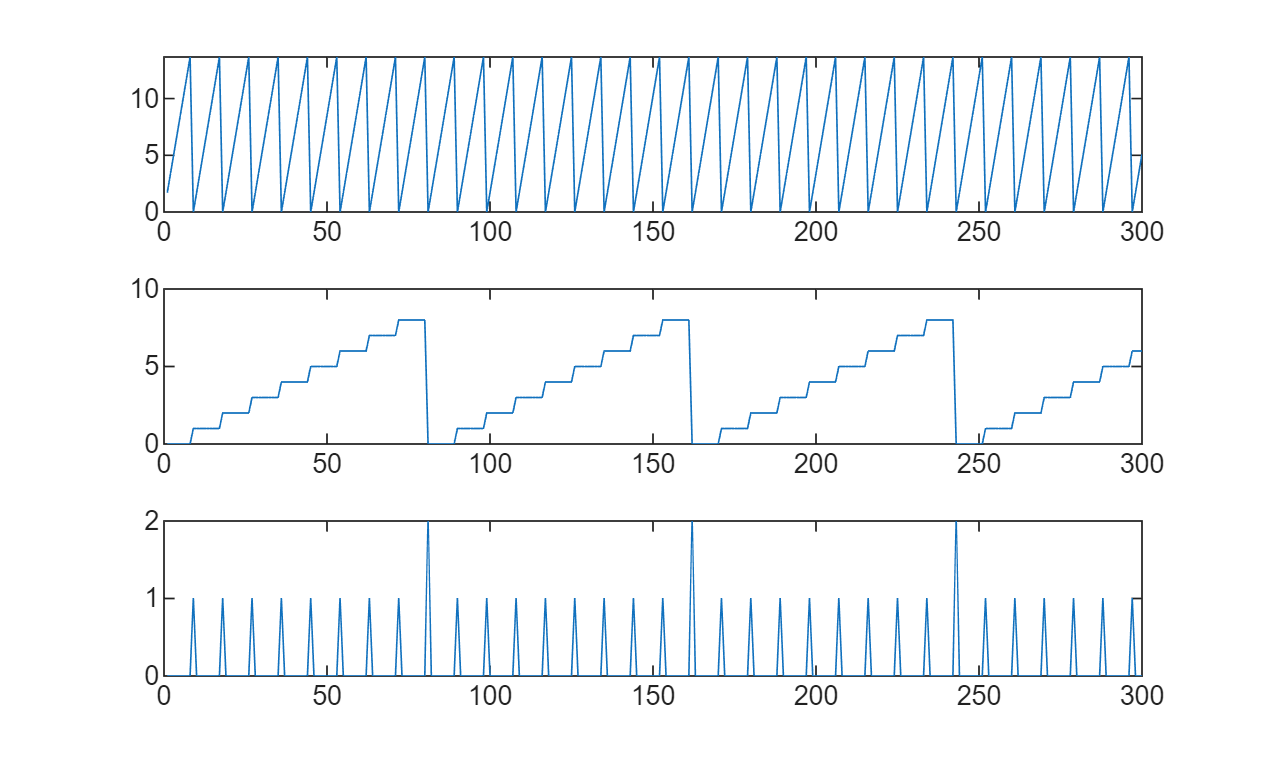


N = size(xs,2);
tiledlayout(3,1)
nexttile
stairs(1:N, xs(1,:));
nexttile
stairs(1:N, xs(2,:));
nexttile
stem(1:N, us(:));